cd 'C:\GitHub\CVUT-MatLab\grant'
startup

## Import JSON

import = jsonImportFn('test.json');

## Zvolené průřezy

designGroups.IndexInSectionSet = [import.DesignGroups.IndexInSectionSet]'+1;

## Nodes

nodes.x = import.Nodes(:,1);
nodes.y = import.Nodes(:,2);
nodes.z = import.Nodes(:,3);
nnodes = numel(nodes.x); 

## Supports

supportNodes = [import.NodalSupports.Node]'+1;
supportDirections = [import.NodalSupports.Fixed]';

kinematic.x.nodes   = supportNodes(supportDirections(:,1));     % node indices with restricted x-direction displacements
kinematic.y.nodes   = supportNodes(supportDirections(:,2));     % node indices with restricted y-direction displacements
kinematic.z.nodes   = supportNodes(supportDirections(:,3));     % node indices with restricted z-direction displacements
kinematic.rx.nodes  = supportNodes(supportDirections(:,4));     % node indices with restricted rx-direction displacements
kinematic.ry.nodes  = supportNodes(supportDirections(:,5));     % node indices with restricted ry-direction displacements
kinematic.rz.nodes  = supportNodes(supportDirections(:,6));     % node indices with restricted rz-direction displacements

nodes.dofs = true(nnodes,6);                    % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1)     = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2)     = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3)     = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4)    = false;    % mark prevented movement in rx-direction
nodes.dofs(kinematic.ry.nodes,5)    = false;    % mark prevented movement in ry-direction
nodes.dofs(kinematic.rz.nodes,6)    = false;    % mark prevented movement in rz-direction

## Beams

beams.nodesHead = [import.FrameElements.HeadNode]'+1;
beams.nodesEnd = [import.FrameElements.EndNode]'+1;

nr = numel(beams.nodesHead);
nset = size(import.SectionSets,1);

### Beams sections

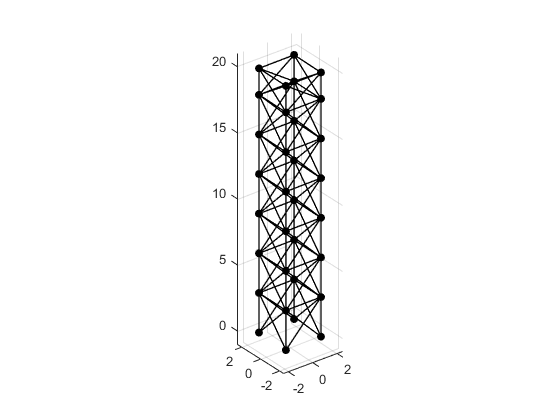

plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
hold off

## Loads

nLoads = size([import.LoadCases],1);
loads.x.nodes = [];             % node indices with x-direction forces
loads.y.nodes = [];             % node indices with y-direction forces
loads.z.nodes = [];             % node indices with z-direction forces
loads.x.value = [];             % magnitude of the x-direction forces
loads.y.value = [];             % magnitude of the y-direction forces
loads.z.value = [];             % magnitude of the z-direction forces

for i = 1:nLoads
    loadNodes = [import.LoadCases(i).NodalForces.Node]'+1;
    loadForces = [import.LoadCases(i).NodalForces.F]';
    loadCond = loadForces ~= 0;
    loads.x.nodes = [loads.x.nodes ; loadNodes(loadCond(:,1))];             % node indices with x-direction forces
    loads.y.nodes = [loads.y.nodes ; loadNodes(loadCond(:,2))];             % node indices with y-direction forces
    loads.z.nodes = [loads.z.nodes ; loadNodes(loadCond(:,3))];             % node indices with z-direction forces
    loads.x.value = [loads.x.value ; loadForces(loadCond(:,1), 1)];         % magnitude of the x-direction forces
    loads.y.value = [loads.y.value ; loadForces(loadCond(:,2), 2)];         % magnitude of the y-direction forces
    loads.z.value = [loads.z.value ; loadForces(loadCond(:,3), 3)];         % magnitude of the z-direction forces
end

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;
localZ = [import.FrameElements.LocalZ]';

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = ZtoBeamsFn(beams,localZ);
% beams.disc      = [import.FrameElements.NoElements];
beams.disc      = ones(nr,1)*7

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.ndofs = max(max(elements.codeNumbers));

endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

## Sections

Odtud mají vliv zvolené průřezy. Proměnné nahoře nejsou ovlivěny zvoleným průřezem. Pro rychlejší výpočet stability pro potřeby optimalizace je možné pouštět cyklus až odtud.

### Zvolené průřezy

% added
modulCond = true;
ng = size([import.DesignGroups.SectionSetIndex]',1);
if modulCond
    floors = ng / 3;
    designGroups.SectionSet = [import.DesignGroups.SectionSetIndex]'+1;
    designGroups.SectionSet = designGroups.SectionSet(1:3);
    designGroups.IndexInSectionSet = [import.DesignGroups.IndexInSectionSet]'+1;
    designGroups.IndexInSectionSet = designGroups.IndexInSectionSet(1:3);
    ng = size(designGroups.IndexInSectionSet,1);
else
    designGroups.SectionSet = [import.DesignGroups.SectionSetIndex]'+1;
    designGroups.IndexInSectionSet = [import.DesignGroups.IndexInSectionSet]'+1; %tohle je prostor pro měnění průřezů pro jednotlivé skupiny
end

#### Ověření zvolených průřezů

Proměnná ***designGroups.IndexInSectionSet ***obsahuje indexy odpovídajcí pořadí ve zvoleném ***sectionSet{k}***, tedy i-tý prvek ***designGroups.IndexInSectionSet***, představuje index proměnné pro i-tou skupinu prutů. Tento index předstvauje pořadí průřezu ze zvolené sady ***sectionSet{k}***, kde k představuje zvolenou sadu parametrem ***designGroups.SectionSet. ***

for i = 1:nset
    sectionSet.AvailableSectionsIndexes{i} = import.SectionSets(i).AvailableSectionsDBIndexes+1;
    sectionSet.maxIndex(i) = size(sectionSet.AvailableSectionsIndexes{i},1);
end
maxIndex = sectionSet.maxIndex(designGroups.SectionSet)';
maxIndexCondition = designGroups.IndexInSectionSet > maxIndex;

if any(maxIndexCondition)
%     error('Index průřezu není v příslušné sadě profilů');
    designGroups.IndexInSectionSet(maxIndexCondition) = maxIndex(maxIndexCondition)
end

### Přiřazení průřezů beamům a elementům


for i = 1:ng
    sections.id(i) = sectionSet.AvailableSectionsIndexes{designGroups.SectionSet(i)}(designGroups.IndexInSectionSet(i));
end

sectionsDB = [import.SectionsDB];
for j = 1:ng
    sections.id(j) = 5;
    
    sections.A(j,1)  = sectionsDB(sections.id(j)).SectionProperties.A;
    sections.Iy(j,1) = sectionsDB(sections.id(j)).SectionProperties.Iy;
    sections.Iz(j,1) = sectionsDB(sections.id(j)).SectionProperties.Iz;
    sections.Ix(j,1) = sectionsDB(sections.id(j)).SectionProperties.Ip;
    sections.E(j,1)  = 210*10^9;
    sections.v(j,1)  = 0.3;
end

% Added
if modulCond
    beams.sections = [import.FrameElements.DesignGroupIndex]'+1;
    beams.sections = repmat(beams.sections(1:nr/floors),[floors,1]);
else
    beams.sections = [import.FrameElements.DesignGroupIndex]'+1;
end

elements.sections = sectionToElementFn(sections,beams);

### Linear analysis

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local,~] = endForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);

### Non-linear analysis

geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);

% volume = sum(elements.sections.A .* transformationMatrix.lengths)

Results = criticalLoadFn(stiffnesMatrix,geometricMatrix,10);

[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

fprintf('1. kritické břemeno: %7.3f\n', sortedValues(1));

## Uložení JSONu s optimalizovanými průřezy

if modulCond
    for i = 1:length(designGroups.IndexInSectionSet)
        for j = 1:length(import.DesignGroups)/length(designGroups.IndexInSectionSet)
            import.DesignGroups(j*i).IndexInSectionSet = designGroups.IndexInSectionSet(i)-1;
        end
    end
else
    for i = 1:length(import.DesignGroups)
        import.DesignGroups(i).IndexInSectionSet = designGroups.IndexInSectionSet(i)-1;
    end
end

output.DesignGroups = import.DesignGroups;

jsonString = jsonencode(output);

% Uložení JSON řetězce do souboru
jsonFileName = 'output.json';
fid = fopen(jsonFileName, 'w');
fprintf(fid, jsonString);
fclose(fid);